
$$\frac{dY}{dx}= \frac{-\lambda}{x^2}(Y^2-Y_{EQ}^2)$$


Here we're solving for an s-wave (n = 0)

For $Y_{EQ}
$, we have


$$Y_{EQ}= \frac{0.192g}{\sqrt g_*}\frac{m}{M_{pl}}\langle\sigma v_0\rangle x^{3/2}e^{-x}$$


Let us start with some assumptions

m = 1000;
g = 100;
sig = 1e-9; 
mpl = 2.44e19;

Now, solving the ODE

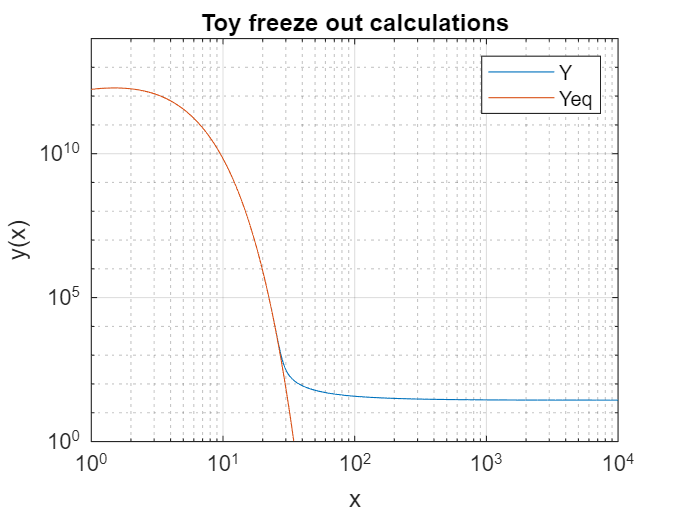


f = @(x, y) (-1/(x.^2)).*(y.^2-(0.192*m*mpl*sig*(x.^(3/2)).*exp(-x)).^2); 
xrange = [1, 1e4];
y0 = 0.192*m*mpl*sig*exp(-1);
[x, y] = ode15s(f, xrange, y0);

figure;
loglog(x, y);
hold on
yeq = 0.192*m*mpl*sig*(x.^(3/2)).*exp(-x);
loglog(x, yeq);
xlabel("x");
ylabel("y(x)");
xlim([1, 1e4]);
ylim([1, 1e14]);
title("Toy freeze out calculations");
grid on


legend('Y', 'Yeq'),

hold off

We can see that up to a certian range, $Y = Y_{EQ}$ is a valid boundary condition. Below, we will plot $\frac{Y}{Y_{EQ}}
$ versus x

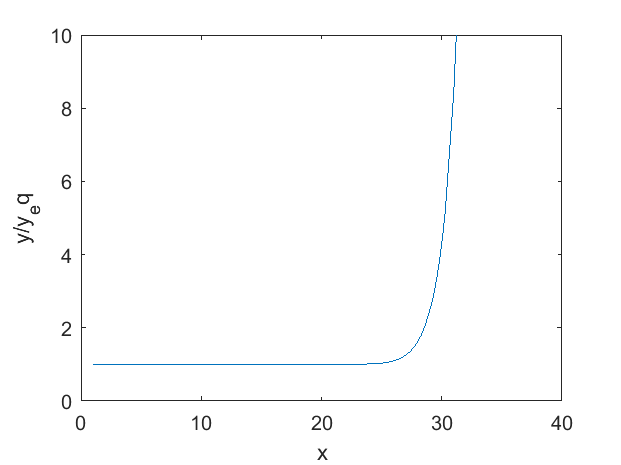

r = y ./ yeq; 
figure;
plot(x, r);
xlabel("x");
ylabel("y/y_eq");
ylim([0, 10]);
xlim([0, 40]);